# Seeeduino XIAO Setup

## Solder the header pins

Like a Pico, the silk screen is underneath, and I used short pins so I can't see them. Here's the pinout.

 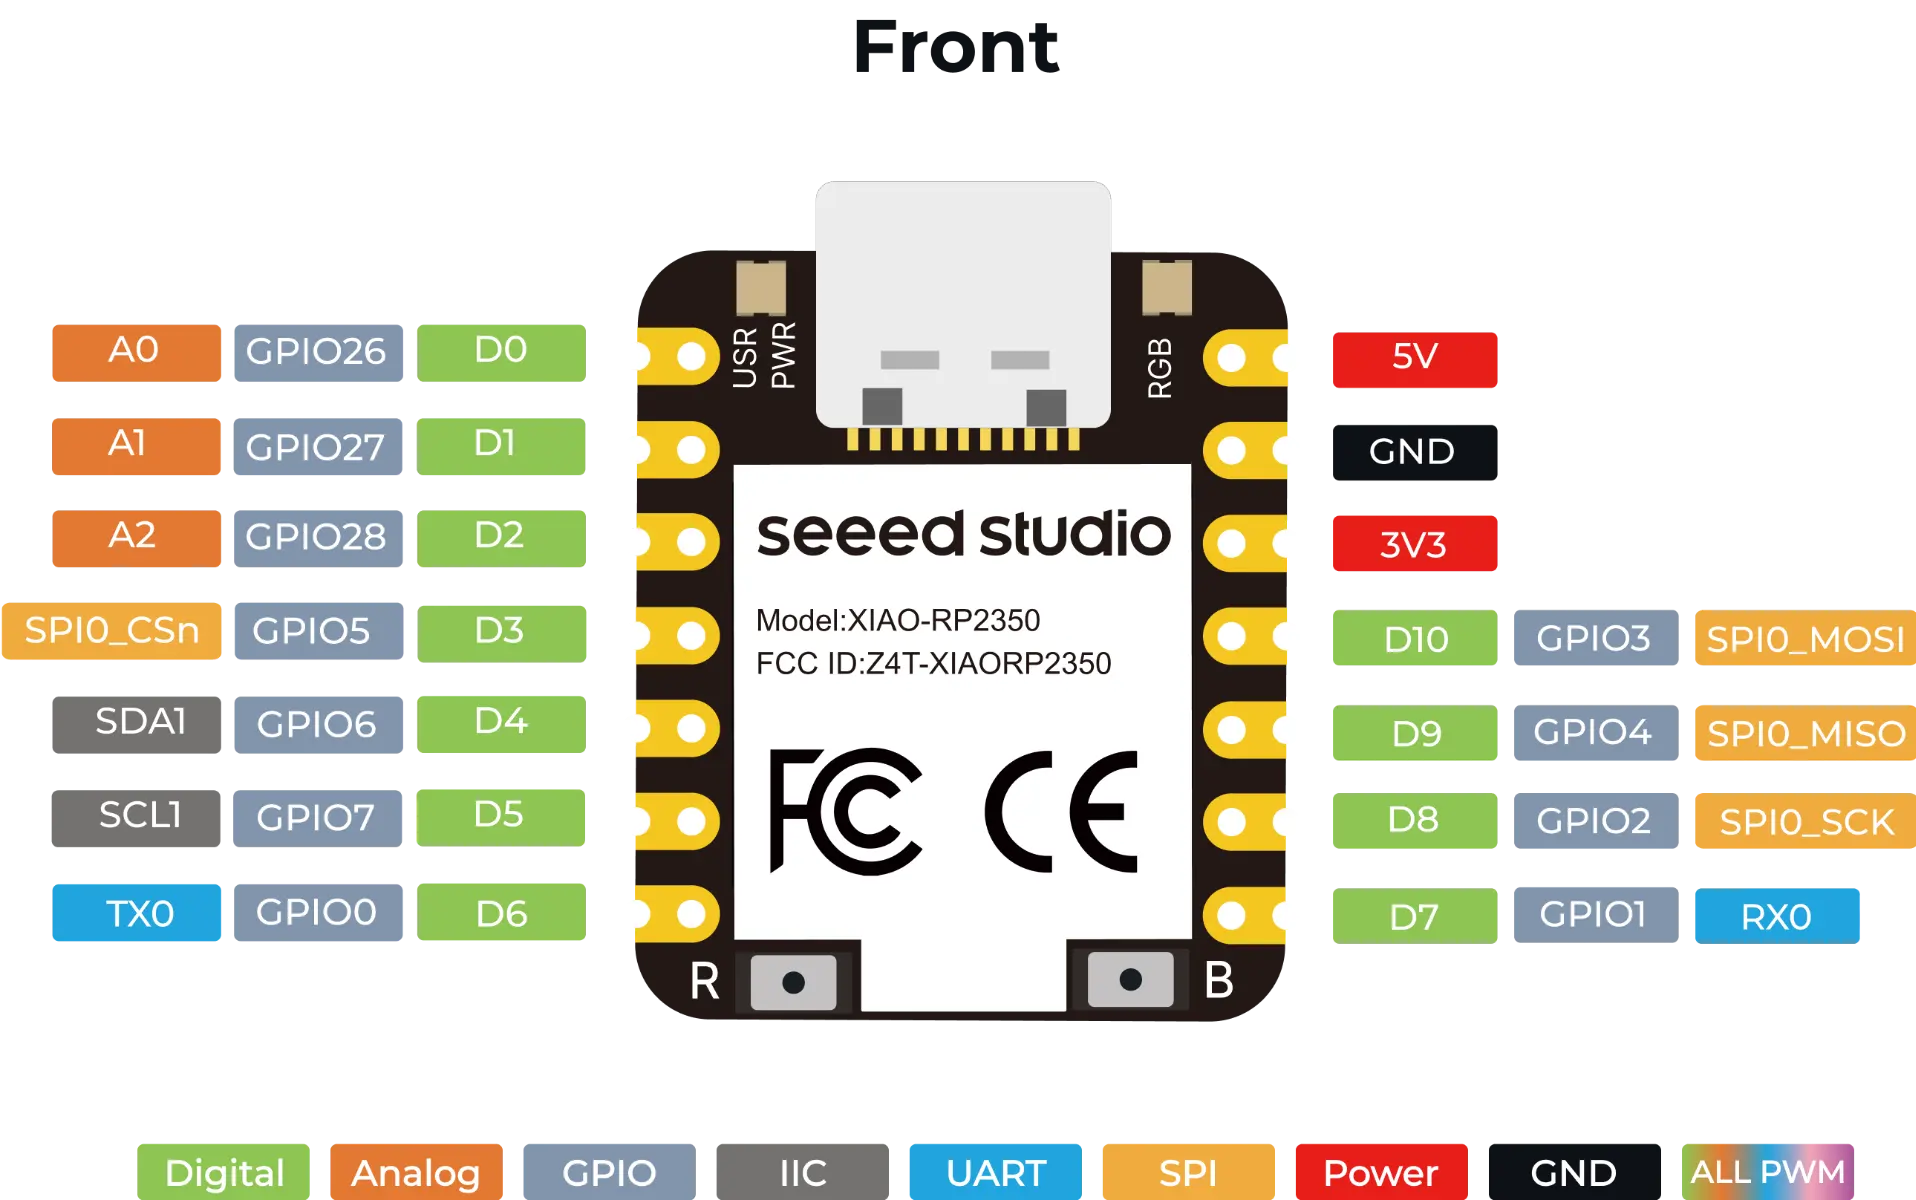

        Figure 1. Seeduino XIAO-RP2350 pinout.

There's just one GND pin, so don't forget to connect it to BOTH ground busses on the solderless breadboard (i.e., need a jumper wire -- blue on far right in Fig. 2 -- connecting the two blue busses).

Here it is on the breadboard -- lots more real estate for building stuff! A $20 Thunderbolt 4 cable worked, but my first attempt with a USBA to USBC cable didn't. Tried another (10" long) USBA-C cable in a USBC hub with both USBC and USB3 ports, and it worked, so apparently it doesn't need to be a TB4 cable but just a USBC cable that supports data, not all of them do. 

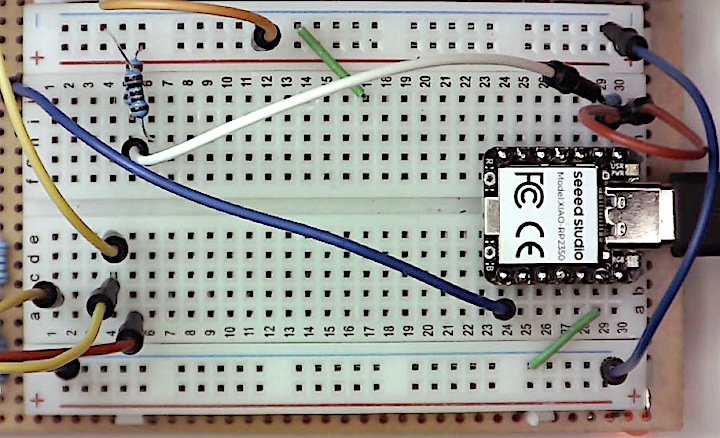

        Figure 2. Seeduino on a mini breadboard, voltage divider and 10k resistor between function generator (orange top) --> A0 and A1. Lower left pin --> blue jumper --> PWM filter and current mirror circuit (yellow jumpers).

## XIAO Software 

Tweaking pscope -- need to renumber pins, and anticipate wanting a programmable delay to slow down data acquisition. But this took some debugging. `pinMode(7, OUTPUT)` is **not** the same as `pinMode(D7, OUTPUT)`, only the later works. So a `const int analogOutputPin `declaration doesn't work, but `#define` does (and beware you can't use `// `comments after a `#define`, only `/* */` ... why?

### Configuring Arduino IDE and uploading

 [https://wiki.seeedstudio.com/xiao_rp2350_arduino/](https://wiki.seeedstudio.com/xiao_rp2350_arduino/) gives directions. I had no success with a USB-A to C cable plugged into a short USBC-USBA(F) connector (on my Macbook Pro). Tried a Thunderbolt4 cable, the 1-button boot from the video, and the IDE showed an "unknown device on /dev/cu.usbmodem2101" (after the OS asked permission to connect a device). After clicking Upload I had to give the OS permission again to connect, and the upload succeeded. 

## MATLAB oscope software

Save pscope.m --> sscope.m (don't forget to change `runBtn.Callback = 'sscope';`). Found what I thought was a bug, unstable triggering, variable frequency and phase. Turns out low frequencies (100's of Hz) vary slow enough that flicker noise was causing false triggering. 1 ADU = 3.3V/2^12 = 0.8mV = 800$\mu$V, so it shouldn't be surprising that noise > 1ADU. If the voltage dwells near the threshold for longer than a sample, our simplistic `trim` algorithm would detect multiple periods. Three fixes are to increase the frequency (i.e., frequency jumper in 4th position), reduce the ADC resolution from 12 bits, or add a delay, e.g., `writeline(seed,'d 20');`. Here's `sscope.m`: 

## Results

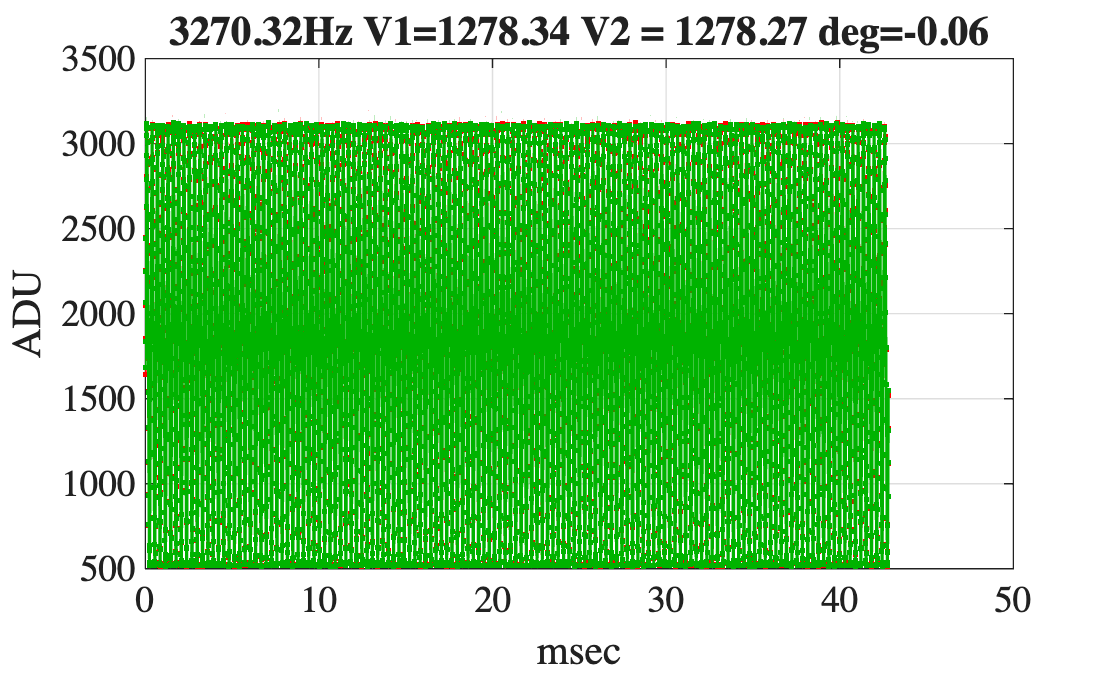

dat.runOnce = true; sscope;

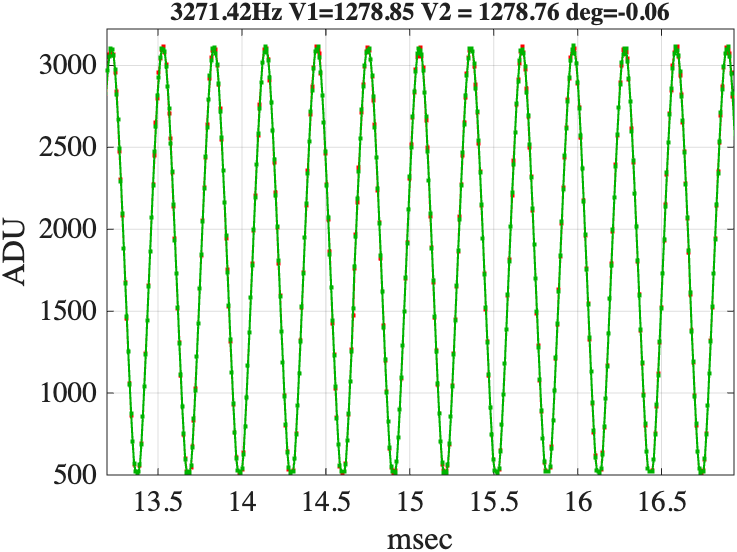

        Figures 3 and 4: sscope display and zoomed in. 

dat.sr

ans = 1.1502e+05

spectrum: 

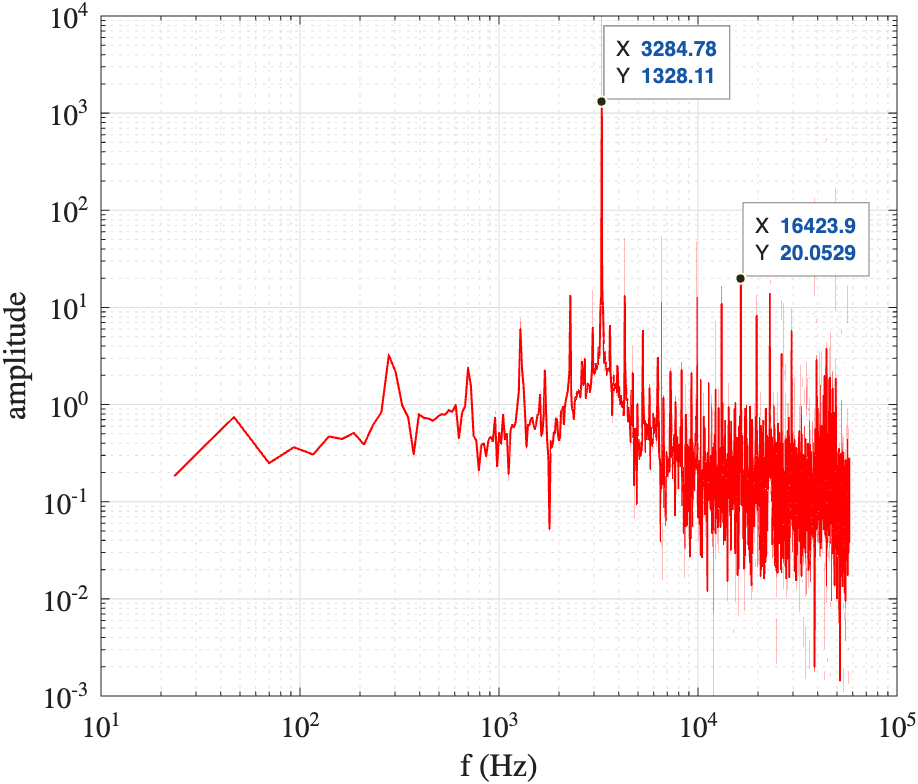

I verified most of the peaks to the right are harmonics -- except the symmetric pair adjacent to the main peak. Harmonic amplitudes are, and the adjacent peaks are symmetrical at frequencies:

harmonicAmpls = abs(dat.fd(dat.npds*(1:6)+1,1))'/length(dat.data)*2

harmonicAmpls = 1.0e+03 *

    1.3281    0.0111    0.0126    0.0109    0.0201    0.0082


df_of_nearest_peaks = [2283.04 4286.52] - 3284.78 % with amplitudes 13.18 and 13.01ADU

df_of_nearest_peaks = 1.0e+03 *

   -1.0017    1.0017


THD = sqrt(sum(harmonicAmpls(2:end).^2)) / harmonicAmpls(1)

THD = 0.0222

which is as good as I've ever seen this XR2206 design perform -- probably because sine shaping is better at this high a frequency.

### Calibrating frequency control

The range of PWM values is now 0-4095 corresponding to ~0-3.3V, so the current mirror pot has to be reduced. Connected the LM317 to the current mirror, `writeline(seed,'p 4095')`, and tweaked the pot until the voltage ~ 1.3V. Next connected the mirror to the function generator shunt jumper.  

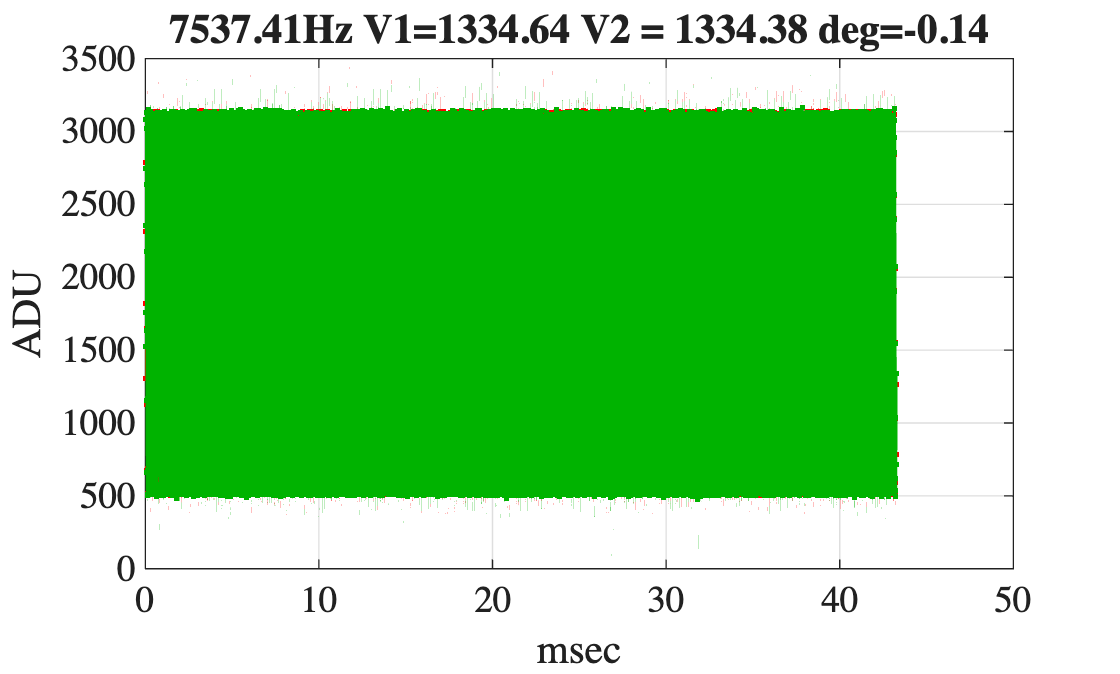

flush(seed) % force buffer to empty
pwmVal = linspace(4095,1.1/3.3*4095,100)';
writeline(seed,'p 4095'); pause(2); % ideally pause 1 minute!
fmeas = zeros(size(pwmVal));
tic;
for i=1:length(pwmVal)
    writeline(seed,['p' num2str(pwmVal(i))]);
    pause(.1); % time for the frequency to stabilize
    dat.runOnce = true;
    sscope; % --> new data in dat
    fmeas(i) = dat.freq; 
end

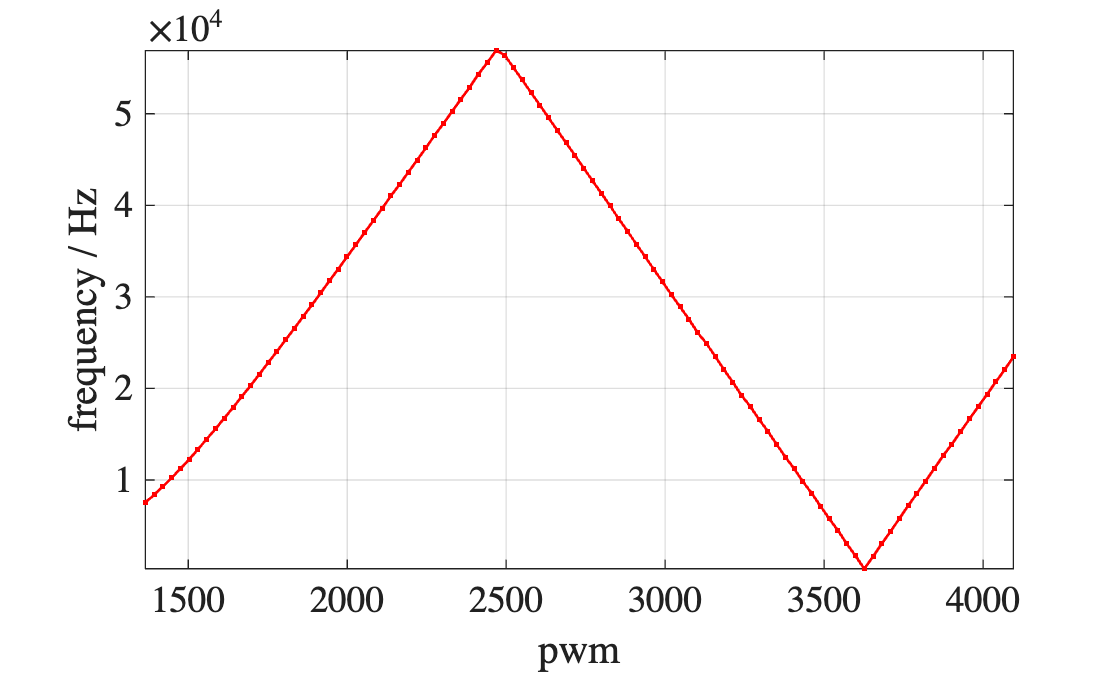

writeline(seed,'p 4095'); % expect to repeat ... 
plot(pwmVal, fmeas, '.-'); axis tight; grid;
xlabel('pwm'); ylabel('frequency / Hz'); 

toc

Elapsed time is 28.980919 seconds.


Double aliasing ... not too different than with the Arduino. I see 4 solutions: 1) restrict the PWM values below ~2500, 2) tweak the function generator's capacitor just like we did for Arduino, 3) unalias -- unreflect, i.e., for PWM on the negative slope, `freq --> dat.sr - freq`, and on the right side, `freq --> dat.sr + freq`. (BTW, the phase shift jumps from ~0 to $\pm180^o$ above the first reflection.) 4) Further reduce the current mirror pot value, increasing the mirrored current. The XR2206 I recall (I think) can sink 3mA, so we could get 3x the frequency range. The actual frequency range was 

fprintf('%.1fkHz < freq < %.1fkHz\n', fmeas(end)/1e3, (dat.sr+fmeas(1))/1e3)

7.3kHz < freq < 131.4kHz


which have a ratio of 18:1, same as Arduino. Cranking down the current mirror pot randomly, 

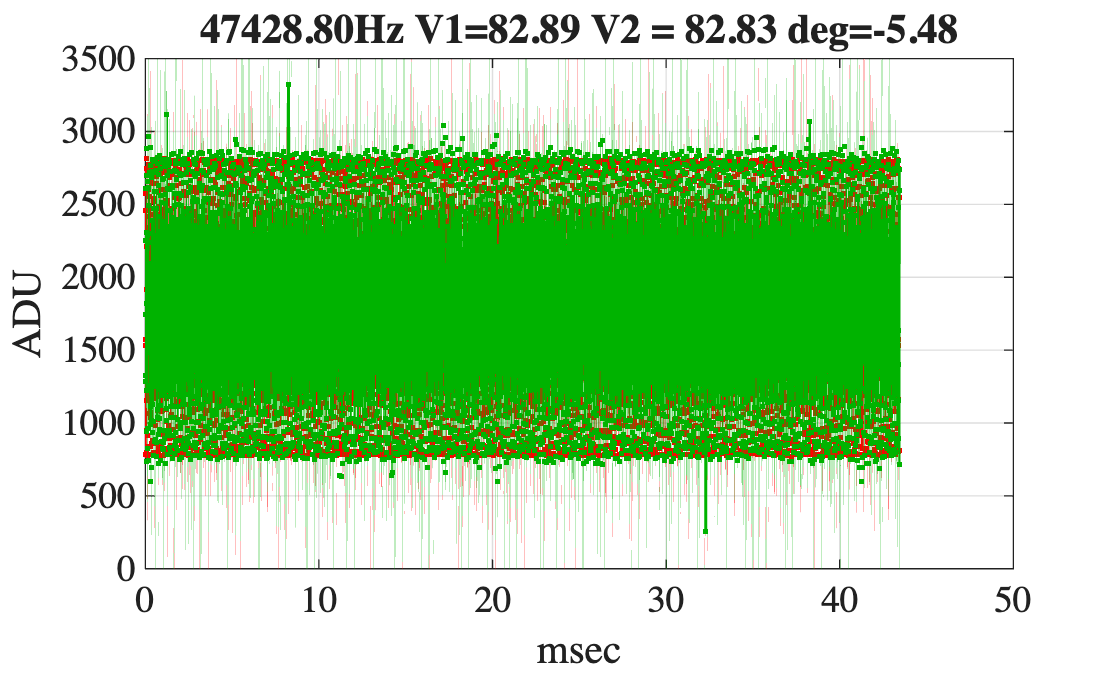

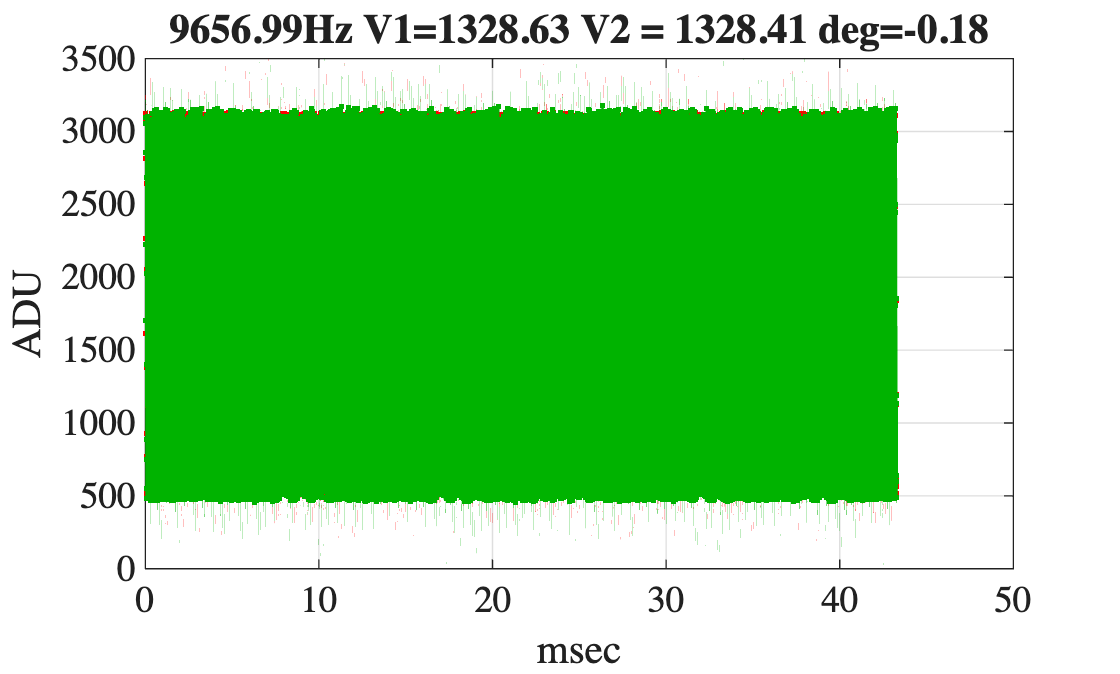

clf; 
fmeas = zeros(size(pwmVal)); 
dphase = fmeas; 
tic;
for i=1:length(pwmVal)
    writeline(seed,['p' num2str(pwmVal(i))]);
    pause(.1); % time for the frequency to stabilize
    dat.runOnce = true;
    sscope; % --> new data in dat
    fmeas(i) = dat.freq; 
    dphase(i) = diff(dat.theta);
end

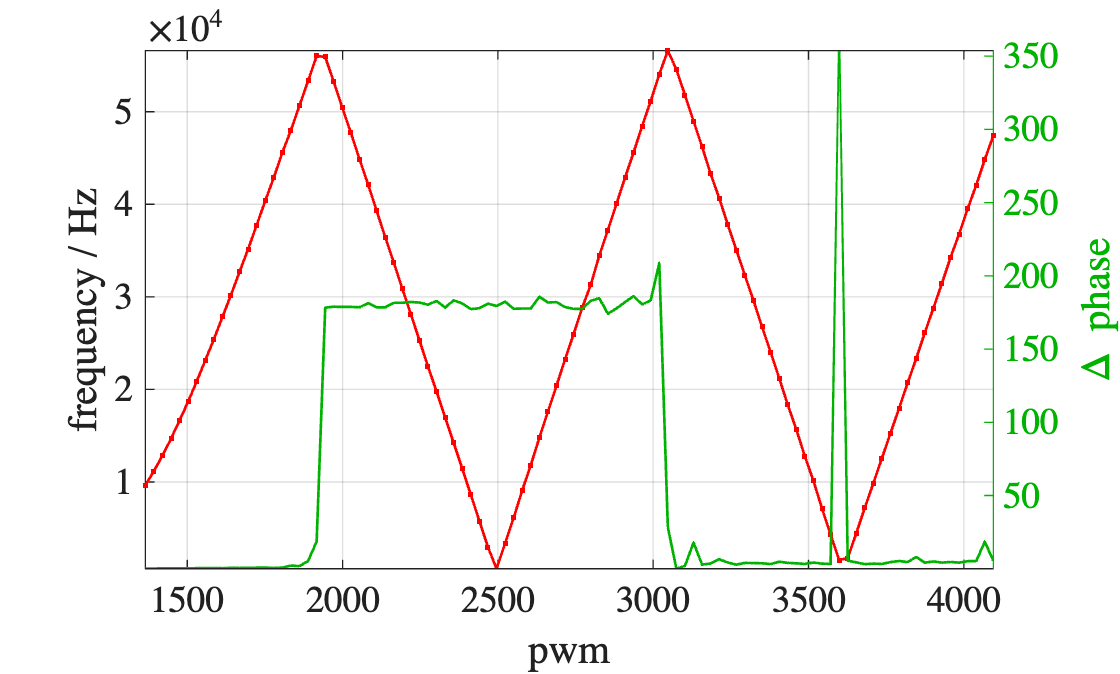

writeline(seed,'p 4095'); % expect to repeat ... 
plot(pwmVal, fmeas, '.-'); axis tight; grid;
xlabel('pwm'); ylabel('frequency / Hz'); 
yyaxis right; 
plot(pwmVal,abs(dphase));
ylabel('\Delta phase')

Phase behaves this way because it's the same signal on 2 channels. 4 reflections means the frequency range is 

fprintf('%.1fkHz < freq < %.1fkHz\n', fmeas(end)/1e3, (2*dat.sr+fmeas(1))/1e3)

9.7kHz < freq < 277.4kHz


That's a frequency ratio of 28:1, not bad! A cool thing is that we can measure practical inductors and resonances in this frequency range -- that just wasn't feasible with Arduino. The above graph (and prior one) are distilled from 1 million voltage measurements, taken in 29 seconds (that includes 10 seconds of pauses).

A lot of tweaking to put this into the curriculum, not something to burden Kurt with now, but I think worthwhile in the future. 